# Revisiting the TSRT method

## Regression Slope analysis

### Sol and MG Slope with the two methods - Plots

Sol n = 12 -  5117 had SRs only in the two fastest velocities and was excluded from the analysis. MG n = 11 - 5117/5119 were excluded because they lack SRs in all velocities.  Sol is represented by the mean since it is normally distributted, and MG by the median.

load Regression_CP.mat
load muscle_data.mat
Descriptives_Sol = groupsummary(TSRT_regression, "Method", {'mean','std','median','max','min'},{'p_sol', 'Rsq_sol'})%Original method

Descriptives_Sol = 2×12 table
    Method    GroupCount                    mean_p_sol                                   std_p_sol                                   median_p_sol                                     max_p_sol                                        min_p_sol                        mean_Rsq_sol          std_Rsq_sol        median_Rsq_sol         max_Rsq_sol           min_Rsq_sol     
    ______    __________    __________________________________________    ________________________________________    __________________________________________    ______________________________________________    ____________________________________________    __________

Descriptives_MG = groupsummary(TSRT_regression, "Method", {'mean','std','median','max','min'},{'p_mg', 'Rsq_mg'})%latency corrected method

Descriptives_MG = 2×12 table
    Method    GroupCount                    mean_p_mg                                     std_p_mg                                    median_p_mg                                     max_p_mg                                      min_p_mg                         mean_Rsq_mg          std_Rsq_mg          median_Rsq_mg         max_Rsq_mg             min_Rsq_mg     
    ______    __________    __________________________________________    ________________________________________    ____________________________________________    ________________________________________    ____________________________________________    _________________</

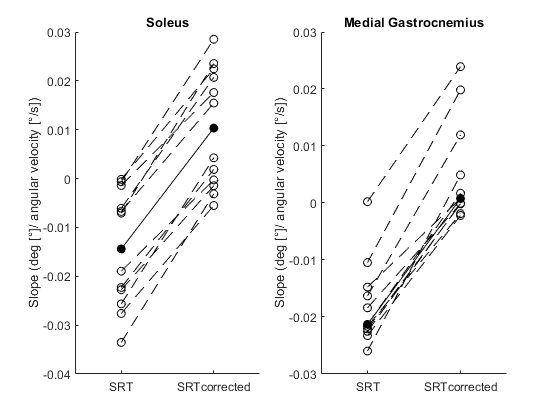

TSRT_regression.Method = categorical(TSRT_regression.Method); 
Slope_sol = TSRT_regression.p_sol(TSRT_regression.Method == "0" & TSRT_regression.Subject ~= "5117",1);
Slope_LC_sol = TSRT_regression.p_sol(TSRT_regression.Method == "1" & TSRT_regression.Subject ~= "5117",1);
Slope_mg = TSRT_regression.p_mg(TSRT_regression.Method == "0" & TSRT_regression.Subject ~= "5117" & TSRT_regression.Subject ~= "5119",1);
Slope_LC_mg = TSRT_regression.p_mg(TSRT_regression.Method == "1" & TSRT_regression.Subject ~= "5117"& TSRT_regression.Subject ~= "5119",1);
y_slope_sol(1,1:12) =  Slope_sol'; y_slope_sol(2,1:12) = Slope_LC_sol';
y_slope_mg(1,1:11) =  Slope_mg'; y_slope_mg(2,1:11) = Slope_LC_mg';
x_slope_sol (1,1:12) = categorical("SRT"); x_slope_sol(2,1:12) = categorical("SRTcorrected");
x_slope_mg (1,1:11) = categorical("SRT"); x_slope_mg(2,1:11) = categorical("SRTcorrected");

subplot(1,2,1)
plot(x_slope_sol,y_slope_sol,'ko'), line(x_slope_sol,y_slope_sol,'color','k', 'linestyle', '--'), %individual values for both methods in sol
ylabel('Slope (deg [°]/ angular velocity [°/s])'), box off, title("Soleus")
hold on, %Sol
plot(x_slope_sol(1:2)', [mean(Slope_sol) mean(Slope_LC_sol)], 'ok', 'MarkerFaceColor','k'), %mean values for both methods in sol
line(x_slope_sol(1:2)', [mean(Slope_sol) mean(Slope_LC_sol)], 'color','k', 'linestyle', '-')
hold off
subplot(1,2,2)%MG
plot(x_slope_mg,y_slope_mg,'ko'), line(x_slope_mg,y_slope_mg,'color','k', 'linestyle', '--'), %individual values for both methods in mg
ylabel('Slope (deg [°]/ angular velocity [°/s])'), box off, title("Medial Gastrocnemius")
hold on, 
plot(x_slope_mg(1:2)', [median(Slope_mg) median(Slope_LC_mg)], 'ok', 'MarkerFaceColor','k'), %mean values for both methods in mg
line(x_slope_mg(1:2)', [median(Slope_mg) median(Slope_LC_mg)], 'color','k', 'linestyle', '-')
hold off

### Slope Sol - Statistics

Both groups have normal distribution and equal variances. 

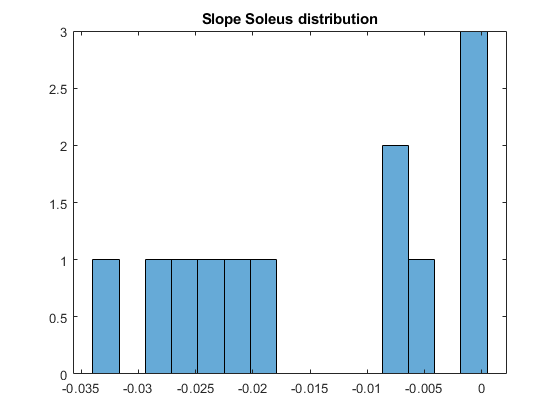

figure,histogram(Slope_sol,15),title('Slope Soleus distribution'),

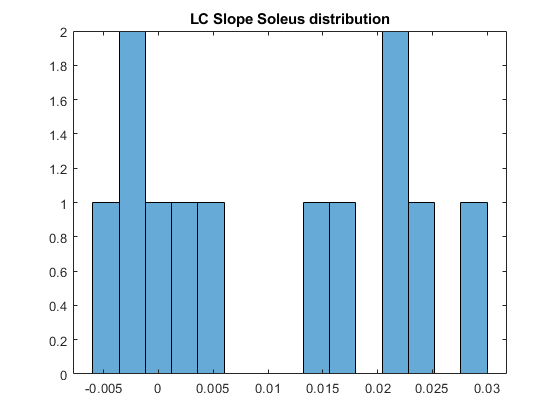

figure,histogram(Slope_LC_sol,15), title('LC Slope Soleus distribution'),

kurtosis_CP = kurtosis(Slope_sol)

kurtosis_CP =           1.50422011180164


kurtosis_TD = kurtosis(Slope_LC_sol)

kurtosis_TD =           1.40103973060887


skewness_CP = skewness(Slope_sol)

skewness_CP =          -0.15517396561896


skewness_TD = skewness(Slope_LC_sol)

skewness_TD =          0.085807978646945


normalitytest(Slope_sol'); 

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.8010 	     0.5425                 1 
KS Stephens Modification       0.8555 	     0.0760                 1 
KS Marsaglia Method            0.8010 	     0.4730                 1 
KS Lilliefors Modification     0.2312 	     0.0758                 1 
Anderson-Darling Test          0.6018 	     0.0706                 1 
Cramer- Von Mises Test         0.1033 	     0.1014                 1 
Shapiro-Wilk Test              0.8938 	     0.1319                 1 
Shapiro-Francia Test           0.9150 	     0.2085                 1 
Jarque-Bera Test               1.1668 	     0.5580                 1 
DAgostino & Pearson Test       3.6949 	     0.1576                 1 


normalitytest(Slope_LC_sol');

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.6628 	     0.7719                 1 
KS Stephens Modification       0.7079 	     0.1500                 1 
KS Marsaglia Method            0.6628 	     0.7045                 1 
KS Lilliefors Modification     0.1913 	     0.2000                 1 
Anderson-Darling Test          0.5977 	     0.1185                 1 
Cramer- Von Mises Test         0.1024 	     0.1041                 1 
Shapiro-Wilk Test              0.8961 	     0.1413                 1 
Shapiro-Francia Test           0.9179 	     0.2262                 1 
Jarque-Bera Test               1.2931 	     0.5239                 1 
DAgostino & Pearson Test       5.0377 	     0.0806                 1 


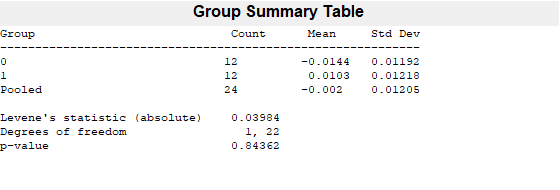

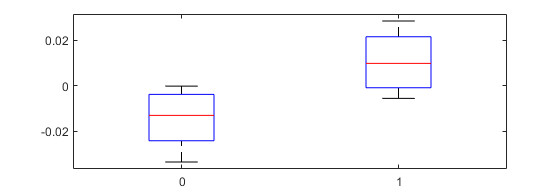

p =          0.843623364356924


p = vartestn(TSRT_regression.p_sol(TSRT_regression.Subject ~= "5117",1),TSRT_regression.Method(TSRT_regression.Subject ~= "5117"),'TestType','LeveneAbsolute')

p = vartestn(TSRT_regression.p_sol(TSRT_regression.Subject ~= "5117",1),TSRT_regression.Method(TSRT_regression.Subject ~= "5117"),'TestType','LeveneQuadratic','display','off')

p =          0.879099953292205


[h,p,ci,stats] = ttest(Slope_sol,Slope_LC_sol) %paired t-test

h =      1


p =       7.69223081629395e-10


ci =        -0.0275619071245901
       -0.0219274274512937


stats = struct with fields:
    tstat: -19.3319165744021
       df: 11
       sd: 0.0044340167509158


stats_slope_sol = mes(Slope_sol,Slope_LC_sol,'hedgesg','exactCi',true) %hedge´s g

stats_slope_sol = struct with fields:
            isDep: 0
            nBoot: 0
        confLevel: 0.95
                n: [2×1 double]
                t: [1×1 struct]
          hedgesg: -1.98286670869166
        hedgesgCi: [2×1 double]
    hedgesgCiType: 'exact analytical'


### Slope MG - Statistics

n = 11. Both groups do not have normal distribution and have equal variances. 

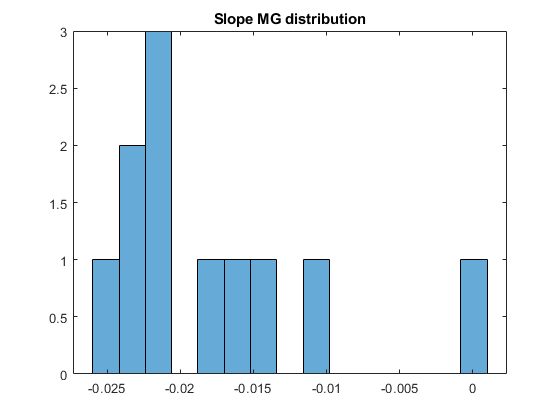

figure,histogram(Slope_mg,15),title('Slope MG distribution'),

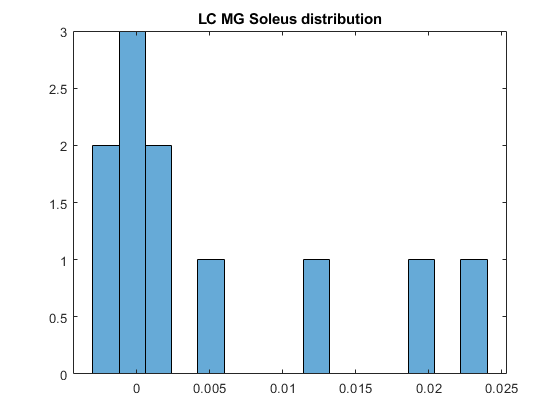

figure,histogram(Slope_LC_mg,15), title('LC MG Soleus distribution'),

kurtosis_CP = kurtosis(Slope_mg)

kurtosis_CP =           4.15729037834727


kurtosis_TD = kurtosis(Slope_LC_mg)

kurtosis_TD =           2.77919396309228


skewness_CP = skewness(Slope_mg)

skewness_CP =           1.36792532171688


skewness_TD = skewness(Slope_LC_mg)

skewness_TD =           1.15213942581881


normalitytest(Slope_mg'); 

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.7403 	     0.6435                 1 
KS Stephens Modification       0.7953 	     0.1270                 1 
KS Marsaglia Method            0.7403 	     0.5695                 1 
KS Lilliefors Modification     0.2232 	     0.1316                 1 
Anderson-Darling Test          0.7298 	     0.0403                 0 
Cramer- Von Mises Test         0.1139 	     0.0726                 1 
Shapiro-Wilk Test              0.8506 	     0.0483                 0 
Shapiro-Francia Test           0.8378 	     0.0328                 0 
Jarque-Bera Test               4.0444 	     0.1324                 1 
DAgostino & Pearson Test       8.7118 	     0.0128                 0 


normalitytest(Slope_LC_mg');

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.9653 	     0.3090                 1 
KS Stephens Modification       1.0370 	     0.0100                 0 
KS Marsaglia Method            0.9653 	     0.2551                 1 
KS Lilliefors Modification     0.2911 	     0.0098                 0 
Anderson-Darling Test          1.2021 	     0.0051                 0 
Cramer- Von Mises Test         0.2136 	     0.0036                 0 
Shapiro-Wilk Test              0.7766 	     0.0073                 0 
Shapiro-Francia Test           0.7833 	     0.0095                 0 
Jarque-Bera Test               2.4560 	     0.2929                 1 
DAgostino & Pearson Test       4.3462 	     0.1138                 1 


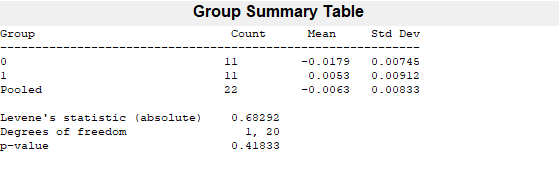

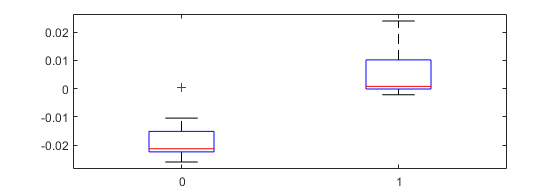

p =           0.41833354747978


p = vartestn(TSRT_regression.p_mg(TSRT_regression.Subject ~= "5117" & TSRT_regression.Subject ~= "5119",1),...
    TSRT_regression.Method(TSRT_regression.Subject ~= "5117" & TSRT_regression.Subject ~= "5119"),'TestType','LeveneAbsolute')

p = vartestn(TSRT_regression.p_mg(TSRT_regression.Subject ~= "5117" & TSRT_regression.Subject ~= "5119",1),...
    TSRT_regression.Method(TSRT_regression.Subject ~= "5117" & TSRT_regression.Subject ~= "5119"),'TestType','LeveneQuadratic','display','off')

p =          0.563535612782144


[p,h,stats] = signrank(Slope_mg,Slope_LC_mg,"method","exact")

p =               0.0009765625


h = logical
   1


stats = struct with fields:
    signedrank: 0


median(Slope_mg)

ans =        -0.0212924101404807


iqr(Slope_mg)

ans =         0.0072812993306973


median(Slope_LC_mg)

ans =       0.000798441258232548


iqr(Slope_LC_mg)

ans =         0.0103406900224581


### Goodness of fit for the linear regression for both muscles - Plots

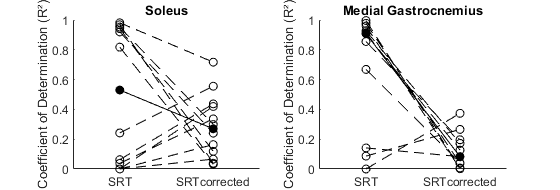

R2_sol = TSRT_regression.Rsq_sol(TSRT_regression.Method == "0" & TSRT_regression.Subject ~= "5117");
R2_LC_sol = TSRT_regression.Rsq_sol(TSRT_regression.Method == "1"& TSRT_regression.Subject ~= "5117");
R2_mg = TSRT_regression.Rsq_mg(TSRT_regression.Method == "0" & TSRT_regression.Subject ~= "5117" & TSRT_regression.Subject ~= "5119");
R2_LC_mg = TSRT_regression.Rsq_mg(TSRT_regression.Method == "1" & TSRT_regression.Subject ~= "5117" & TSRT_regression.Subject ~= "5119");
y_r2_sol(1,1:12) =  R2_sol'; y_r2_sol(2,1:12) = R2_LC_sol';
y_r2_mg(1,1:11) =  R2_mg'; y_r2_mg(2,1:11) = R2_LC_mg';
x_r2_sol (1,1:12) = categorical("SRT"); x_r2_sol(2,1:12) = categorical("SRTcorrected"); 
x_r2_mg (1,1:11) = categorical("SRT"); x_r2_mg(2,1:11) = categorical("SRTcorrected"); 
subplot(1,2,1) %Sol
plot(x_r2_sol,y_r2_sol,'ko'), line(x_r2_sol,y_r2_sol,'color','k', 'linestyle', '--'), % individual values for both methods
ylabel('Coefficient of Determination (R²)'), box off, title("Soleus")
hold on, 
plot(x_r2_sol(1:2)', [median(R2_sol) median(R2_LC_sol)], 'ok', 'MarkerFaceColor','k'), %group data
line(x_r2_sol(1:2)', [median(R2_sol) median(R2_LC_sol)], 'color','k', 'linestyle', '-')
hold off
subplot(1,2,2)% MG
plot(x_r2_mg,y_r2_mg,'ko'), line(x_r2_mg,y_r2_mg,'color','k', 'linestyle', '--'), %ind
ylabel('Coefficient of Determination (R²)'), box off, title("Medial Gastrocnemius")
hold on, 
plot(x_r2_mg(1:2)', [median(R2_mg) median(R2_LC_mg)], 'ok', 'MarkerFaceColor','k'), %group
line(x_r2_mg(1:2)', [median(R2_mg) median(R2_LC_mg)], 'color','k', 'linestyle', '-')
hold off

### Goodness of fit for the linear regression for Sol - Statistics

R² in the original method is not normally distributed, groups do not have equal variances. n = 12, 5117 was excluded.

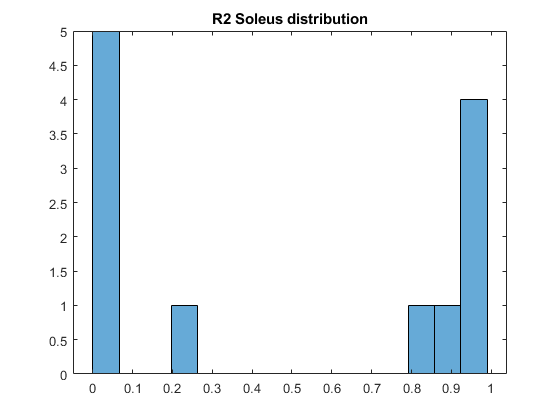

figure,histogram(R2_sol,15),title('R2 Soleus distribution'),

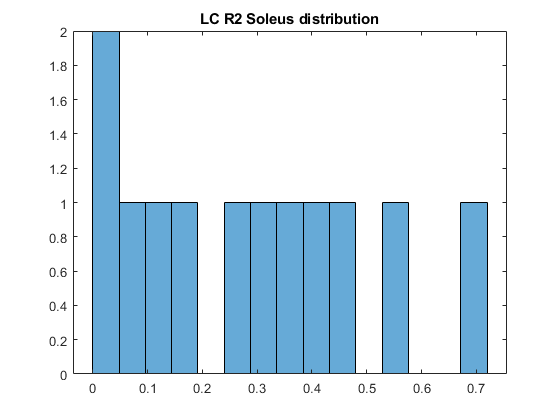

figure,histogram(R2_LC_sol,15), title('LC R2 Soleus distribution'),

kurtosis_CP = kurtosis(R2_sol)

kurtosis_CP =           1.07822371117522


kurtosis_TD = kurtosis(R2_LC_sol)

kurtosis_TD =           2.30265398157148


skewness_CP = skewness(R2_sol)

skewness_CP =        -0.0295622806701254


skewness_TD = skewness(R2_LC_sol)

skewness_TD =          0.533932225366844


normalitytest(R2_sol'); 

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.8951 	     0.3995                 1 
KS Stephens Modification       0.9560 	     0.0348                 0 
KS Marsaglia Method            0.8951 	     0.3394                 1 
KS Lilliefors Modification     0.2584 	     0.0261                 0 
Anderson-Darling Test          1.4390 	     0.0018                 0 
Cramer- Von Mises Test         0.2303 	     0.0023                 0 
Shapiro-Wilk Test              0.7450 	     0.0024                 0 
Shapiro-Francia Test           0.7782 	     0.0064                 0 
Jarque-Bera Test               1.8484 	     0.3969                 1 
DAgostino & Pearson Test       13.2157 	     0.0013                 0 


normalitytest(R2_LC_sol');

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.4455 	     0.9888                 1 
KS Stephens Modification       0.4758 	     0.1500                 1 
KS Marsaglia Method            0.4455 	     0.9741                 1 
KS Lilliefors Modification     0.1286 	     0.2000                 1 
Anderson-Darling Test          0.2814 	     0.6400                 1 
Cramer- Von Mises Test         0.0352 	     0.7676                 1 
Shapiro-Wilk Test              0.9393 	     0.4886                 1 
Shapiro-Francia Test           0.9504 	     0.5515                 1 
Jarque-Bera Test               0.8133 	     0.6659                 1 
DAgostino & Pearson Test       1.0067 	     0.6045                 1 


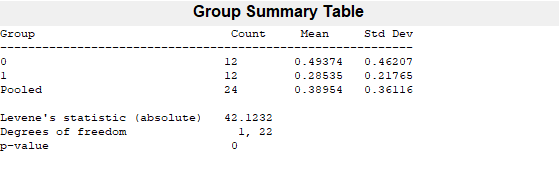

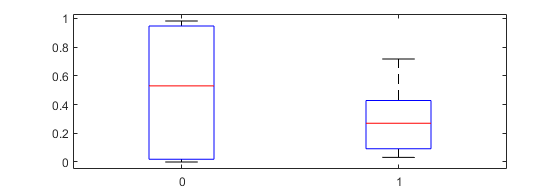

p =       1.57580357632436e-06


p = vartestn(TSRT_regression.Rsq_sol(TSRT_regression.Subject ~= "5117",1),TSRT_regression.Method(TSRT_regression.Subject ~= "5117"),'TestType','LeveneAbsolute')

p = vartestn(TSRT_regression.Rsq_sol(TSRT_regression.Subject ~= "5117",1),TSRT_regression.Method(TSRT_regression.Subject ~= "5117"),'TestType','LeveneQuadratic','display','off')

p =       7.16408716071749e-07


[p,h,stats] = signrank(R2_sol,R2_LC_sol,'method','exact') %Wilcoxon sign rank test

p =              0.30126953125


h = logical
   0


stats = struct with fields:
    signedrank: 53


median(R2_sol)

ans =          0.529926335367954


iqr(R2_sol)

ans =          0.927911389618919


median(R2_LC_sol)

ans =          0.269661304671857


iqr(R2_LC_sol)

ans =          0.335949983420645


### Goodness of fit for the linear regression for MG - Statistics

R² in the original method is not normally distributed, groups do not have equal variances. n = 11, 5117/5119 were excluded.

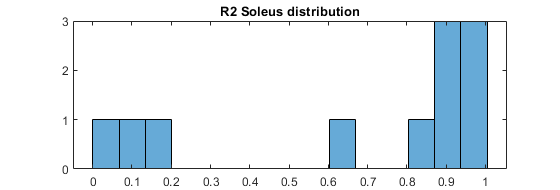

histogram(R2_mg,15),title('R2 Soleus distribution'),

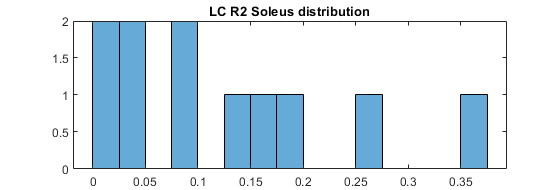

histogram(R2_LC_mg,15), title('LC R2 Soleus distribution'),

kurtosis_CP = kurtosis(R2_mg)

kurtosis_CP =           1.99608869105087


kurtosis_TD = kurtosis(R2_LC_mg)

kurtosis_TD =           2.80296550921163


skewness_CP = skewness(R2_mg)

skewness_CP =         -0.902255368679131


skewness_TD = skewness(R2_LC_mg)

skewness_TD =          0.875315354168481


normalitytest(R2_mg'); 

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               1.0318 	     0.2374                 1 
KS Stephens Modification       1.1084 	     0.0100                 0 
KS Marsaglia Method            1.0318 	     0.1918                 1 
KS Lilliefors Modification     0.3111 	     0.0038                 0 
Anderson-Darling Test          1.4233 	     0.0019                 0 
Cramer- Von Mises Test         0.2479 	     0.0014                 0 
Shapiro-Wilk Test              0.7420 	     0.0033                 0 
Shapiro-Francia Test           0.7596 	     0.0057                 0 
Jarque-Bera Test               1.9544 	     0.3764                 1 
DAgostino & Pearson Test       2.9467 	     0.2292                 1 


normalitytest(R2_LC_mg');

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.6305 	     0.8215                 1 
KS Stephens Modification       0.6773 	     0.1500                 1 
KS Marsaglia Method            0.6305 	     0.7555                 1 
KS Lilliefors Modification     0.1901 	     0.2000                 1 
Anderson-Darling Test          0.4322 	     0.3045                 1 
Cramer- Von Mises Test         0.0635 	     0.3401                 1 
Shapiro-Wilk Test              0.9077 	     0.2331                 1 
Shapiro-Francia Test           0.9123 	     0.2207                 1 
Jarque-Bera Test               1.4225 	     0.4910                 1 
DAgostino & Pearson Test       2.7827 	     0.2487                 1 


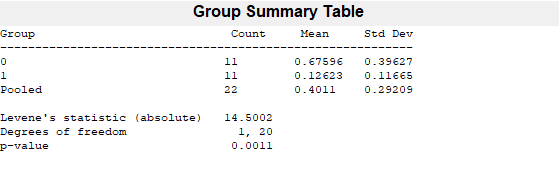

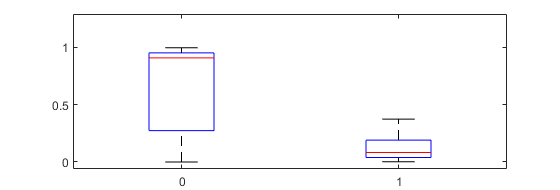

p =        0.00110199963114886


p = vartestn(TSRT_regression.Rsq_mg(TSRT_regression.Subject ~= "5117" & TSRT_regression.Subject ~= "5119",1),...
    TSRT_regression.Method(TSRT_regression.Subject ~= "5117" & TSRT_regression.Subject ~= "5119"),'TestType','LeveneAbsolute')

p = vartestn(TSRT_regression.Rsq_mg(TSRT_regression.Subject ~= "5117" & TSRT_regression.Subject ~= "5119",1),...
    TSRT_regression.Method(TSRT_regression.Subject ~= "5117" & TSRT_regression.Subject ~= "5119"),'TestType','LeveneQuadratic','display','off')

p =        0.00937296456243133


[p,h,stats] = signrank(R2_mg,R2_LC_mg,'method','exact') %Wilcoxon sign rank test

p =                0.009765625


h = logical
   1


stats = struct with fields:
    signedrank: 61


median(R2_mg)

ans =          0.908061046837029


iqr(R2_mg)

ans =          0.678074527159225


median(R2_LC_mg)

ans =         0.0829593243693601


iqr(R2_LC_mg)

ans =          0.151258406032602


### TSRT SOL 

Not normal, equal variances.

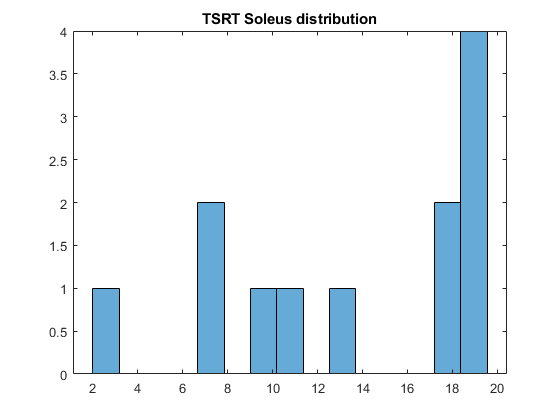

TSRT_sol = TSRT_regression.p_sol(TSRT_regression.Method == "0" & TSRT_regression.Subject ~= "5117",2);
TSRT_LC_sol = TSRT_regression.p_sol(TSRT_regression.Method == "1"& TSRT_regression.Subject ~= "5117",2);
figure,histogram(TSRT_sol,15),title('TSRT Soleus distribution'),

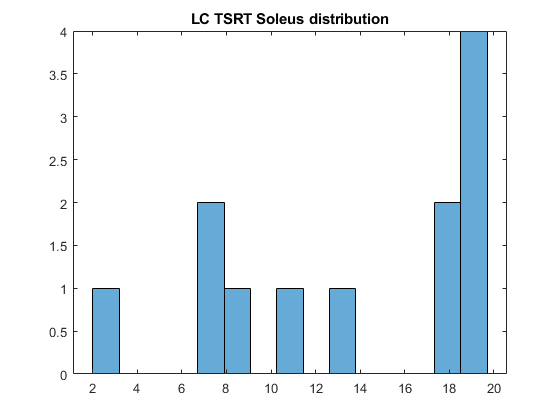

figure,histogram(TSRT_LC_sol,15), title('LC TSRT Soleus distribution'),

kurtosis_CP = kurtosis(TSRT_sol)

kurtosis_CP =           1.70914805367415


kurtosis_TD = kurtosis(TSRT_LC_sol)

kurtosis_TD =            1.6800719619372


skewness_CP = skewness(TSRT_sol)

skewness_CP =         -0.454928793480639


skewness_TD = skewness(TSRT_LC_sol)

skewness_TD =         -0.439935508567149


normalitytest(TSRT_sol'); 

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.9097 	     0.3794                 1 
KS Stephens Modification       0.9715 	     0.0309                 0 
KS Marsaglia Method            0.9097 	     0.3210                 1 
KS Lilliefors Modification     0.2626 	     0.0218                 0 
Anderson-Darling Test          0.8101 	     0.0283                 0 
Cramer- Von Mises Test         0.1298 	     0.0442                 0 
Shapiro-Wilk Test              0.8521 	     0.0390                 0 
Shapiro-Francia Test           0.8716 	     0.0627                 1 
Jarque-Bera Test               1.2471 	     0.5360                 1 
DAgostino & Pearson Test       2.4819 	     0.2891                 1 


normalitytest(TSRT_LC_sol');

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.8903 	     0.4062                 1 
KS Stephens Modification       0.9508 	     0.0360                 0 
KS Marsaglia Method            0.8903 	     0.3455                 1 
KS Lilliefors Modification     0.2570 	     0.0277                 0 
Anderson-Darling Test          0.7841 	     0.0317                 0 
Cramer- Von Mises Test         0.1251 	     0.0513                 1 
Shapiro-Wilk Test              0.8565 	     0.0441                 0 
Shapiro-Francia Test           0.8765 	     0.0716                 1 
Jarque-Bera Test               1.2582 	     0.5331                 1 
DAgostino & Pearson Test       2.6394 	     0.2672                 1 


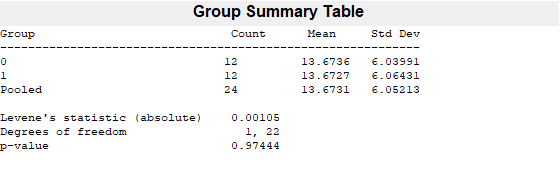

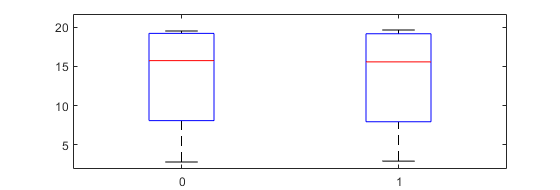

p =          0.974436713758368


p = vartestn(TSRT_regression.p_sol(TSRT_regression.Subject ~= "5117",2),TSRT_regression.Method(TSRT_regression.Subject ~= "5117"),'TestType','LeveneAbsolute')

p = vartestn(TSRT_regression.p_sol(TSRT_regression.Subject ~= "5117",2),TSRT_regression.Method(TSRT_regression.Subject ~= "5117"),'TestType','LeveneQuadratic','display','off')

p =          0.982099033251212


[p,h,stats] = signrank(TSRT_sol,TSRT_LC_sol) %paired t-test

p =              0.90966796875


h = logical
   0


stats = struct with fields:
    signedrank: 37


median(TSRT_sol)

ans =           15.7437816665011


iqr(TSRT_sol)

ans =           11.1048322839928


median(TSRT_LC_sol)

ans =           15.5823258082038


iqr(TSRT_LC_sol)

ans =           11.2148016652067


### TSRT MG 

Not normal, equal variances.

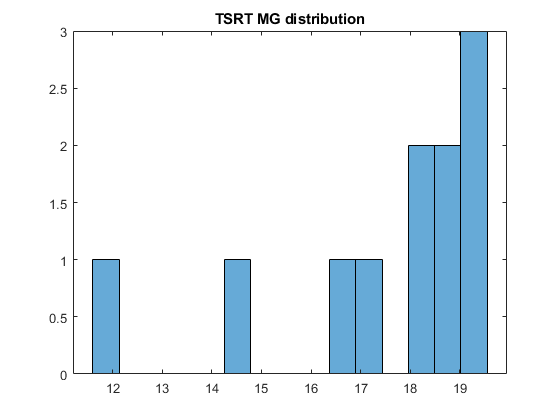

TSRT_mg = TSRT_regression.p_mg(TSRT_regression.Method == "0" & TSRT_regression.Subject ~= "5117" & TSRT_regression.Subject ~= "5119",2);
TSRT_LC_mg = TSRT_regression.p_mg(TSRT_regression.Method == "1" & TSRT_regression.Subject ~= "5117" & TSRT_regression.Subject ~= "5119",2);
figure,histogram(TSRT_mg,15),title('TSRT MG distribution'),

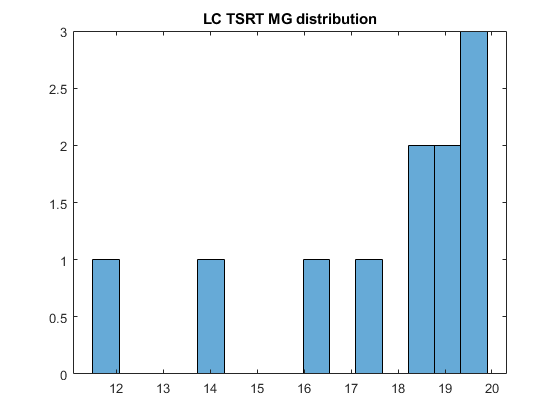

figure,histogram(TSRT_LC_mg,15), title('LC TSRT MG distribution'),

kurtosis_CP = kurtosis(TSRT_mg)

kurtosis_CP =           3.56283750879376


kurtosis_TD = kurtosis(TSRT_LC_mg)

kurtosis_TD =           3.30176868834249


skewness_CP = skewness(TSRT_mg)

skewness_CP =          -1.33589029498652


skewness_TD = skewness(TSRT_LC_mg)

skewness_TD =          -1.23517504441358


normalitytest(TSRT_mg'); 

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.8826 	     0.4173                 1 
KS Stephens Modification       0.9481 	     0.0367                 0 
KS Marsaglia Method            0.8826 	     0.3530                 1 
KS Lilliefors Modification     0.2661 	     0.0285                 0 
Anderson-Darling Test          1.0112 	     0.0117                 0 
Cramer- Von Mises Test         0.1718 	     0.0124                 0 
Shapiro-Wilk Test              0.7968 	     0.0120                 0 
Shapiro-Francia Test           0.7957 	     0.0124                 0 
Jarque-Bera Test               3.4170 	     0.1811                 1 
DAgostino & Pearson Test       7.0678 	     0.0292                 0 


normalitytest(TSRT_LC_mg');

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.8626 	     0.4464                 1 
KS Stephens Modification       0.9267 	     0.0421                 0 
KS Marsaglia Method            0.8626 	     0.3798                 1 
KS Lilliefors Modification     0.2601 	     0.0362                 0 
Anderson-Darling Test          0.8932 	     0.0197                 0 
Cramer- Von Mises Test         0.1522 	     0.0223                 0 
Shapiro-Wilk Test              0.8214 	     0.0223                 0 
Shapiro-Francia Test           0.8220 	     0.0226                 0 
Jarque-Bera Test               2.8388 	     0.2419                 1 
DAgostino & Pearson Test       5.8161 	     0.0546                 1 


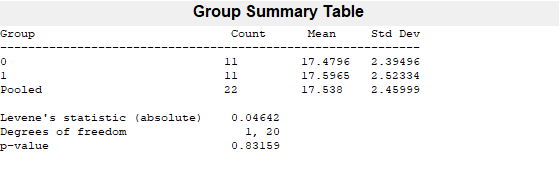

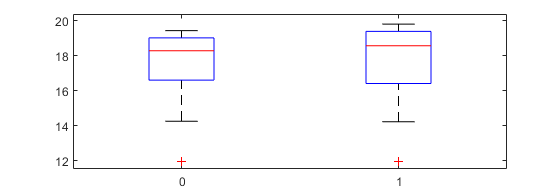

p =          0.831591121236127


p = vartestn(TSRT_regression.p_mg(TSRT_regression.Subject ~= "5117" & TSRT_regression.Subject ~= "5119",2),...
    TSRT_regression.Method(TSRT_regression.Subject ~= "5117" & TSRT_regression.Subject ~= "5119"),'TestType','LeveneAbsolute')

p = vartestn(TSRT_regression.p_mg(TSRT_regression.Subject ~= "5117" & TSRT_regression.Subject ~= "5119",2),...
    TSRT_regression.Method(TSRT_regression.Subject ~= "5117" & TSRT_regression.Subject ~= "5119"),'TestType','LeveneQuadratic','display','off')

p =          0.882412638750158


[p,h,stats] = signrank(TSRT_mg,TSRT_LC_mg) %paired t-test

p =                  0.1015625


h = logical
   0


stats = struct with fields:
    signedrank: 14


median(TSRT_mg)

ans =           18.2879177282763


iqr(TSRT_mg)

ans =           2.41165172571545


median(TSRT_LC_mg)

ans =           18.5731923513438


iqr(TSRT_LC_mg)

ans =           2.97188024020841


## SRT vs. stretch velocities (original method)

Since article 2 (Fast cyclic_DF_group.mlx) already calculated DSRT with latency correction, here the analysis of the original method is performed. 

load Fast_cyclic_DF_all.mat
TSRT_main_all.Group = categorical(TSRT_main_all.Group);% make group a categorical var
TSRT_main_all.Velocity_round = TSRT_main_all.Velocity; % new var for rounded velocity to allow settting it as categorical
TSRT_main_all.Velocity_round(TSRT_main_all.Velocity_round <75) = 50;
TSRT_main_all.Velocity_round(TSRT_main_all.Velocity_round > 75 & TSRT_main_all.Velocity_round < 140 ) = 100;
TSRT_main_all.Velocity_round(TSRT_main_all.Velocity_round > 140 & TSRT_main_all.Velocity_round < 230 ) = 200;
TSRT_main_all.Velocity_round(TSRT_main_all.Velocity_round > 230) = 300;
TSRT_main_all.Velocity_round = categorical(TSRT_main_all.Velocity_round);
TSRT_main = TSRT_main_all(TSRT_main_all.Subject ~= "5105" ,:); % exclude case study (5105)
TSRT_main = TSRT_main(TSRT_main.cond_mvc_sol == 1 & TSRT_main.cond_mvc_mg == 1 & TSRT_main.Group == "CP",:);%remove invalid trials (mvc_cond == 0) + TD
TSRT_Sol = TSRT_main(:,{'Subject','Group','Trial','Velocity','DSRT_Sol','DSRT_Sol_Lat','Velocity_round'}); %separate vars of interrest for sol
TSRT_Sol = TSRT_Sol(TSRT_Sol.DSRT_Sol_Lat ~=0,:); %remove trials without DRST for soleus and TD
TSRT_MG = TSRT_main(:,{'Subject','Group','Trial','Velocity','DSRT_MG','DSRT_MG_Lat','Velocity_round'}); %separate vars of interrest for mg
TSRT_MG = TSRT_MG(TSRT_MG.DSRT_MG_Lat ~=0,:);%remove trials without DRST for mg and TD

### SRT Sol

Vectors for each velocity are not normally distributed and do not have equal variances. n = 12 (5117 excluded).

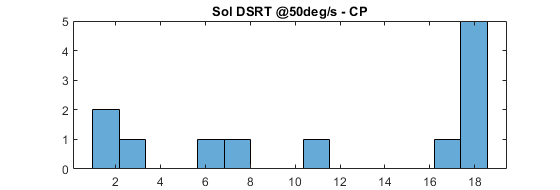

CP_Sol_50_median_descriptives = groupsummary(TSRT_Sol(TSRT_Sol.Velocity_round == "50",:), ...
    "Subject",'median','DSRT_Sol');
CP_Sol_100_median_descriptives = groupsummary(TSRT_Sol(TSRT_Sol.Velocity_round == "100",:), ...
    "Subject",'median','DSRT_Sol');
CP_Sol_200_median_descriptives = groupsummary(TSRT_Sol(TSRT_Sol.Velocity_round == "200" & TSRT_Sol.Subject ~= "5117",:), ...
    "Subject",'median','DSRT_Sol');
CP_Sol_300_median_descriptives = groupsummary(TSRT_Sol(TSRT_Sol.Velocity_round == "300" & TSRT_Sol.Subject ~= "5117",:), ...
    "Subject",'median','DSRT_Sol');
CP_allvel_median_sol = zeros(12,4); %join medians of each subject in 4 cols to use Friedman
CP_allvel_median_sol(:,1) = table2array(CP_Sol_50_median_descriptives(:,3));
CP_allvel_median_sol(:,2) = table2array(CP_Sol_100_median_descriptives(:,3));
CP_allvel_median_sol(:,3) = table2array(CP_Sol_200_median_descriptives(:,3));
CP_allvel_median_sol(:,4) = table2array(CP_Sol_300_median_descriptives(:,3));
CP_Sol_Vel_mediangr(1:12,1) = CP_allvel_median_sol(:,1);%all 4 dsrt in 1 col, 1 col for grouping (vartestn test)
CP_Sol_Vel_mediangr(1:12,2) = 50;
CP_Sol_Vel_mediangr(13:24,1) = CP_allvel_median_sol(:,2);
CP_Sol_Vel_mediangr(13:24,2) = 100;
CP_Sol_Vel_mediangr(25:36,1) = CP_allvel_median_sol(:,3);
CP_Sol_Vel_mediangr(25:36,2) = 200;
CP_Sol_Vel_mediangr(37:48,1) = CP_allvel_median_sol(:,4);
CP_Sol_Vel_mediangr(37:48,2) = 300;
histogram(CP_allvel_median_sol(:,1),15),title('Sol DSRT @50deg/s - CP'),

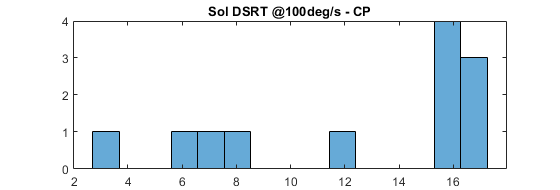

histogram(CP_allvel_median_sol(:,2),15),title('Sol DSRT @100deg/s - CP'),

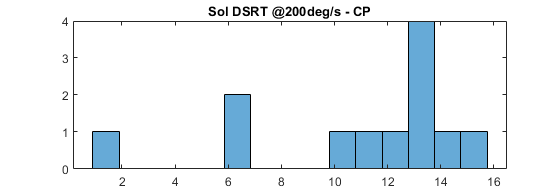

histogram(CP_allvel_median_sol(:,3),15),title('Sol DSRT @200deg/s - CP'),

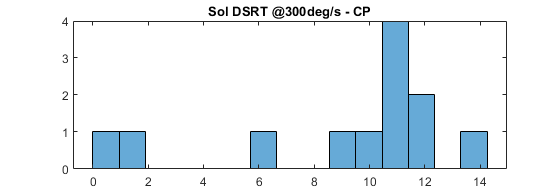

histogram(CP_allvel_median_sol(:,4),15),title('Sol DSRT @300deg/s - CP'),

kurtosis_50 = kurtosis(CP_allvel_median_sol(:,1))

kurtosis_50 =           1.42690296935165


kurtosis_100 = kurtosis(CP_allvel_median_sol(:,2))

kurtosis_100 =           1.83117143488055


kurtosis_200 = kurtosis(CP_allvel_median_sol(:,3))

kurtosis_200 =           3.09296934718233


kurtosis_300 = kurtosis(CP_allvel_median_sol(:,4))

kurtosis_300 =           2.96937551345402


skewness_50 = skewness(CP_allvel_median_sol(:,1))

skewness_50 =          -0.34645453727256


skewness_100 = skewness(CP_allvel_median_sol(:,2))

skewness_100 =         -0.683005509816735


skewness_200 = skewness(CP_allvel_median_sol(:,3))

skewness_200 =          -1.11050381881978


skewness_300 = skewness(CP_allvel_median_sol(:,4))

skewness_300 =          -1.07462925515506


normalitytest(CP_allvel_median_sol(:,1)'); 

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.9061 	     0.3843                 1 
KS Stephens Modification       0.9677 	     0.0318                 0 
KS Marsaglia Method            0.9061 	     0.3254                 1 
KS Lilliefors Modification     0.2616 	     0.0228                 0 
Anderson-Darling Test          0.9144 	     0.0179                 0 
Cramer- Von Mises Test         0.1410 	     0.0314                 0 
Shapiro-Wilk Test              0.8260 	     0.0188                 0 
Shapiro-Francia Test           0.8548 	     0.0403                 0 
Jarque-Bera Test               1.4774 	     0.4777                 1 
DAgostino & Pearson Test       5.0457 	     0.0802                 1 


normalitytest(CP_allvel_median_sol(:,2)');

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               1.1219 	     0.1612                 1 
KS Stephens Modification       1.1982 	     0.0100                 0 
KS Marsaglia Method            1.1219 	     0.1277                 1 
KS Lilliefors Modification     0.3239 	     0.0011                 0 
Anderson-Darling Test          1.2002 	     0.0051                 0 
Cramer- Von Mises Test         0.2111 	     0.0039                 0 
Shapiro-Wilk Test              0.8003 	     0.0094                 0 
Shapiro-Francia Test           0.8159 	     0.0153                 0 
Jarque-Bera Test               1.6161 	     0.4457                 1 
DAgostino & Pearson Test       2.6555 	     0.2651                 1 


normalitytest(CP_allvel_median_sol(:,3)');

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.8450 	     0.4729                 1 
KS Stephens Modification       0.9024 	     0.0481                 0 
KS Marsaglia Method            0.8450 	     0.4073                 1 
KS Lilliefors Modification     0.2439 	     0.0469                 0 
Anderson-Darling Test          0.8897 	     0.0200                 0 
Cramer- Von Mises Test         0.1599 	     0.0177                 0 
Shapiro-Wilk Test              0.8500 	     0.0367                 0 
Shapiro-Francia Test           0.8471 	     0.0330                 0 
Jarque-Bera Test               2.4708 	     0.2907                 1 
DAgostino & Pearson Test       4.6774 	     0.0965                 1 


normalitytest(CP_allvel_median_sol(:,4)');

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.9524 	     0.3245                 1 
KS Stephens Modification       1.0171 	     0.0167                 0 
KS Marsaglia Method            0.9524 	     0.2711                 1 
KS Lilliefors Modification     0.2749 	     0.0127                 0 
Anderson-Darling Test          0.9967 	     0.0125                 0 
Cramer- Von Mises Test         0.1733 	     0.0118                 0 
Shapiro-Wilk Test              0.8367 	     0.0253                 0 
Shapiro-Francia Test           0.8357 	     0.0248                 0 
Jarque-Bera Test               2.3101 	     0.3150                 1 
DAgostino & Pearson Test       4.2400 	     0.1200                 1 


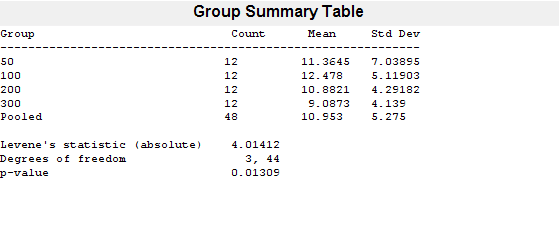

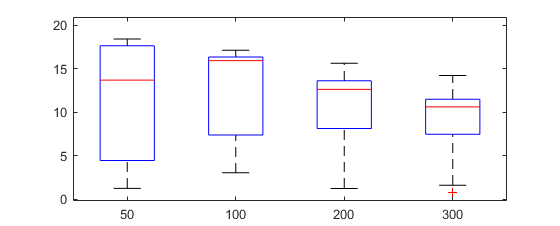

p =         0.0130861934220332


p = vartestn(CP_Sol_Vel_mediangr(:,1),CP_Sol_Vel_mediangr(:,2),'TestType','LeveneAbsolute')

p = vartestn(CP_Sol_Vel_mediangr(:,1),CP_Sol_Vel_mediangr(:,2),'TestType','LeveneQuadratic','display','off')

p =         0.0253541378859289


[p,tbl,stats] = friedman(CP_allvel_median_sol, 1,'on')

p =         0.0084847788643051


tbl = 4×6 cell array
    {'Source' }    {'SS'  }    {'df'}    {'MS'              }    {'Chi-sq'  }    {'Prob>Chi-sq'       }
    {'Columns'}    {[19.5]}    {[ 3]}    {[             6.5]}    {[    11.7]}    {[0.0084847788643051]}
    {'Error'  }    {[40.5]}    {[33]}    {[1.22727272727273]}    {0×0 double}    {0×0 double          }
    {'Total'  }    {[  60]}    {[47]}    {0×0 double        }    {0×0 double}    {0×0 double          }


stats = struct with fields:
       source: 'friedman'
            n: 12
    meanranks: [2.9167 3.1667 2.4167 1.5000]
        sigma: 1.2910


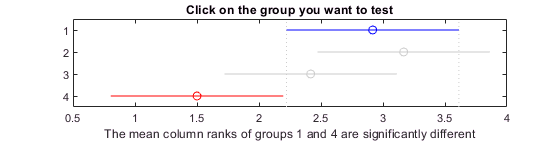

Note: Intervals can be used for testing but are not simultaneous confidence intervals.


c =     1.0000    2.0000   -1.6405   -0.2500    1.1405    1.0000
    1.0000    3.0000   -0.8905    0.5000    1.8905    1.0000
    1.0000    4.0000    0.0262    1.4167    2.8072    0.0431
    2.0000    3.0000   -0.6405    0.7500    2.1405    0.9284
    2.0000    4.0000    0.2762    1.6667    3.0572    0.0094
    3.0000    4.0000   -0.4738    0.9167    2.3072    0.4919


m =     2.9167    0.3727
    3.1667    0.3727
    2.4167    0.3727
    1.5000    0.3727


h =   Figure (26: Multiple comparison of mean column ranks) with properties:

      Number: 26
        Name: 'Multiple comparison of mean column ranks'
       Color: [0.9400 0.9400 0.9400]
    Position: [681 838.2000 560 140.8000]
       Units: 'pixels'

  Show all properties


gnames = 4×1 char array
    '1'
    '2'
    '3'
    '4'


[c,m,h,gnames] = multcompare(stats,'CType','bonferroni')

median(CP_allvel_median_sol(:,1))

ans = 13.6958

iqr(CP_allvel_median_sol(:,1))

ans = 13.1774

median(CP_allvel_median_sol(:,2))

ans = 15.9350

iqr(CP_allvel_median_sol(:,2))

ans = 8.9503

median(CP_allvel_median_sol(:,3))

ans = 12.6407

iqr(CP_allvel_median_sol(:,3))

ans = 5.4843

median(CP_allvel_median_sol(:,4))

ans = 10.6273

iqr(CP_allvel_median_sol(:,4))

ans = 4.0202

### SRT MG

1 vector does not have normal distribituion, groups have unequal variances.

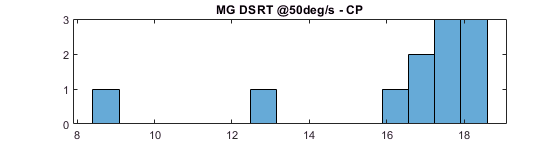

CP_mg_50_median_descriptives = groupsummary(TSRT_MG(TSRT_MG.Velocity_round == "50" & TSRT_MG.Subject ~= "5117" ...
    & TSRT_MG.Subject ~= "5119",:),"Subject",'median','DSRT_MG');
CP_mg_100_median_descriptives = groupsummary(TSRT_MG(TSRT_MG.Velocity_round == "100" & TSRT_MG.Subject ~= "5117" ...
    & TSRT_MG.Subject ~= "5119",:),"Subject",'median','DSRT_MG');
CP_mg_200_median_descriptives = groupsummary(TSRT_MG(TSRT_MG.Velocity_round == "200" & TSRT_MG.Subject ~= "5117" ...
    & TSRT_MG.Subject ~= "5119",:),"Subject",'median','DSRT_MG');
CP_mg_300_median_descriptives = groupsummary(TSRT_MG(TSRT_MG.Velocity_round == "300"  & TSRT_MG.Subject ~= "5117" ...
    & TSRT_MG.Subject ~= "5119",:),"Subject",'median','DSRT_MG');
CP_allvel_median_mg = zeros(11,4); %join medians of each subject in 4 cols to use Friedman test
CP_allvel_median_mg(:,1) = table2array(CP_mg_50_median_descriptives(:,3));
CP_allvel_median_mg(:,2) = table2array(CP_mg_100_median_descriptives(:,3));
CP_allvel_median_mg(:,3) = table2array(CP_mg_200_median_descriptives(:,3));
CP_allvel_median_mg(:,4) = table2array(CP_mg_300_median_descriptives(:,3));
CP_MG_Vel_mediangr = CP_allvel_median_mg(:,1);
CP_MG_Vel_mediangr(:,2) = 50;
CP_MG_Vel_mediangr(12:22,1) = CP_allvel_median_mg(:,2);
CP_MG_Vel_mediangr(12:22,2) = 100;
CP_MG_Vel_mediangr(23:33,1) = CP_allvel_median_mg(:,3);
CP_MG_Vel_mediangr(23:33,2) = 200;
CP_MG_Vel_mediangr(34:44,1) = CP_allvel_median_mg(:,4);
CP_MG_Vel_mediangr(34:44,2) = 300;
histogram(CP_allvel_median_mg(:,1),15),title('MG DSRT @50deg/s - CP'),

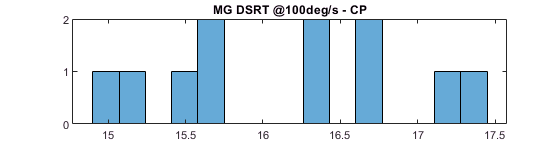

histogram(CP_allvel_median_mg(:,2),15),title('MG DSRT @100deg/s - CP'),

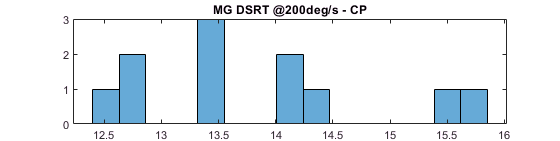

histogram(CP_allvel_median_mg(:,3),15),title('MG DSRT @200deg/s - CP'),

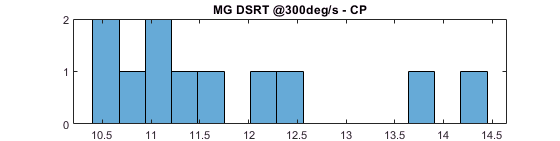

histogram(CP_allvel_median_mg(:,4),15),title('MG DSRT @300deg/s - CP'),

kurtosis_50 = kurtosis(CP_allvel_median_mg(:,1))

kurtosis_50 = 4.7947

kurtosis_100 = kurtosis(CP_allvel_median_mg(:,2))

kurtosis_100 = 1.6730

kurtosis_200 = kurtosis(CP_allvel_median_mg(:,3))

kurtosis_200 = 2.2950

kurtosis_300 = kurtosis(CP_allvel_median_mg(:,4))

kurtosis_300 = 2.6957

skewness_50 = skewness(CP_allvel_median_mg(:,1))

skewness_50 = -1.7654

skewness_100 = skewness(CP_allvel_median_mg(:,2))

skewness_100 = 0.0651

skewness_200 = skewness(CP_allvel_median_mg(:,3))

skewness_200 = 0.6353

skewness_300 = skewness(CP_allvel_median_mg(:,4))

skewness_300 = 0.9754

normalitytest(CP_allvel_median_mg(:,1)'); 

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               1.0457 	     0.2242                 1 
KS Stephens Modification       1.1233 	     0.0100                 0 
KS Marsaglia Method            1.0457 	     0.1803                 1 
KS Lilliefors Modification     0.3153 	     0.0031                 0 
Anderson-Darling Test          1.5678 	     0.0010                 0 
Cramer- Von Mises Test         0.2864 	     0.0005                 0 
Shapiro-Wilk Test              0.6971 	     0.0012                 0 
Shapiro-Francia Test           0.6851 	     0.0014                 0 
Jarque-Bera Test               7.1902 	     0.0275                 0 
DAgostino & Pearson Test       13.2212 	     0.0013                 0 


normalitytest(CP_allvel_median_mg(:,2)');

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.5970 	     0.8683                 1 
KS Stephens Modification       0.6413 	     0.1500                 1 
KS Marsaglia Method            0.5970 	     0.8083                 1 
KS Lilliefors Modification     0.1800 	     0.2000                 1 
Anderson-Darling Test          0.3350 	     0.5073                 1 
Cramer- Von Mises Test         0.0528 	     0.4712                 1 
Shapiro-Wilk Test              0.9353 	     0.4831                 1 
Shapiro-Francia Test           0.9548 	     0.6501                 1 
Jarque-Bera Test               0.8149 	     0.6653                 1 
DAgostino & Pearson Test       1.7655 	     0.4136                 1 


normalitytest(CP_allvel_median_mg(:,3)');

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.5565 	     0.9161                 1 
KS Stephens Modification       0.5978 	     0.1500                 1 
KS Marsaglia Method            0.5565 	     0.8668                 1 
KS Lilliefors Modification     0.1678 	     0.2000                 1 
Anderson-Darling Test          0.4196 	     0.3261                 1 
Cramer- Von Mises Test         0.0575 	     0.4086                 1 
Shapiro-Wilk Test              0.9131 	     0.2703                 1 
Shapiro-Francia Test           0.9258 	     0.3166                 1 
Jarque-Bera Test               0.9677 	     0.6164                 1 
DAgostino & Pearson Test       1.3270 	     0.5150                 1 


normalitytest(CP_allvel_median_mg(:,4)');

 
Test Name                  Test Statistic   p-value   Normality (1:Normal,0:Not Normal)
-----------------------    --------------  ---------  --------------------------------
KS Limiting Form               0.6403 	     0.8068                 1 
KS Stephens Modification       0.6879 	     0.1500                 1 
KS Marsaglia Method            0.6403 	     0.7395                 1 
KS Lilliefors Modification     0.1931 	     0.2000                 1 
Anderson-Darling Test          0.6598 	     0.0547                 1 
Cramer- Von Mises Test         0.1002 	     0.1118                 1 
Shapiro-Wilk Test              0.8629 	     0.0673                 1 
Shapiro-Francia Test           0.8722 	     0.0770                 1 
Jarque-Bera Test               1.7867 	     0.4093                 1 
DAgostino & Pearson Test       3.1857 	     0.2033                 1 


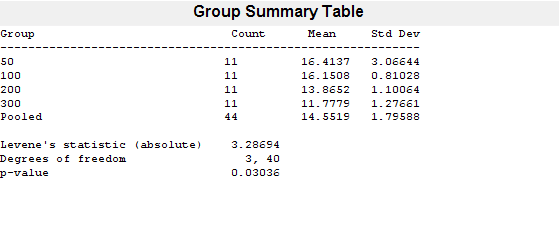

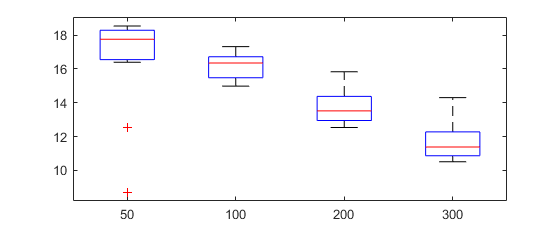

p = 0.0304

p = vartestn(CP_MG_Vel_mediangr(:,1),CP_MG_Vel_mediangr(:,2),'TestType','LeveneAbsolute')

p = vartestn(CP_MG_Vel_mediangr(:,1),CP_MG_Vel_mediangr(:,2),'TestType','LeveneQuadratic','display','off')

p = 0.1293

[p,tbl,stats1] = friedman(CP_allvel_median_mg, 1,'on')

p = 2.4333e-05

tbl = 4×6 cell array
    {'Source' }    {'SS'     }    {'df'}    {'MS'      }    {'Chi-sq'  }    {'Prob>Chi-sq'}
    {'Columns'}    {[40.0909]}    {[ 3]}    {[ 13.3636]}    {[ 24.0545]}    {[ 2.4333e-05]}
    {'Error'  }    {[14.9091]}    {[30]}    {[  0.4970]}    {0×0 double}    {0×0 double   }
    {'Total'  }    {[     55]}    {[43]}    {0×0 double}    {0×0 double}    {0×0 double   }


stats1 = struct with fields:
       source: 'friedman'
            n: 11
    meanranks: [3.5455 3.1818 2.1818 1.0909]
        sigma: 1.2910


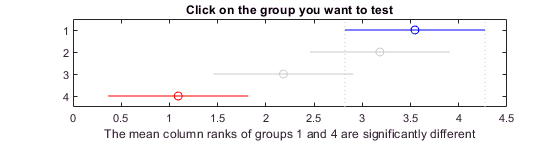

Note: Intervals can be used for testing but are not simultaneous confidence intervals.


c =     1.0000    2.0000   -1.0887    0.3636    1.8159    1.0000
    1.0000    3.0000   -0.0887    1.3636    2.8159    0.0795
    1.0000    4.0000    1.0022    2.4545    3.9069    0.0000
    2.0000    3.0000   -0.4523    1.0000    2.4523    0.4157
    2.0000    4.0000    0.6386    2.0909    3.5432    0.0009
    3.0000    4.0000   -0.3614    1.0909    2.5432    0.2851


m =     3.5455    0.3892
    3.1818    0.3892
    2.1818    0.3892
    1.0909    0.3892


h =   Figure (29: Multiple comparison of mean column ranks) with properties:

      Number: 29
        Name: 'Multiple comparison of mean column ranks'
       Color: [0.9400 0.9400 0.9400]
    Position: [681 838.2000 560 140.8000]
       Units: 'pixels'

  Show all properties


gnames = 4×1 char array
    '1'
    '2'
    '3'
    '4'


[c,m,h,gnames] = multcompare(stats1,'CType','bonferroni')

median(CP_allvel_median_mg(:,1))

ans = 17.7519

iqr(CP_allvel_median_mg(:,1))

ans = 1.7346

median(CP_allvel_median_mg(:,2))

ans = 16.3498

iqr(CP_allvel_median_mg(:,2))

ans = 1.2464

median(CP_allvel_median_mg(:,3))

ans = 13.5222

iqr(CP_allvel_median_mg(:,3))

ans = 1.4284

median(CP_allvel_median_mg(:,4))

ans = 11.3876

iqr(CP_allvel_median_mg(:,4))

ans = 1.4063

### Summarizing latency duration 

load add_info.mat
Sol_lat = add_info.Sol_lat(add_info.Group == "CP" & add_info.Subject ~= "5101" &  add_info.Subject ~= "5102" ...
     & add_info.Subject ~= "5103" & add_info.Subject ~= "5105" & add_info.Subject ~= "5113" & add_info.Subject ~= "5120"...
     & add_info.Subject ~= "5117");     
mean(Sol_lat)

ans = 27.9167

std(Sol_lat)

ans = 3.3699

max(Sol_lat)

ans = 33

min(Sol_lat)

ans = 23

MG_lat = add_info.MG_lat(add_info.Group == "CP" & add_info.Subject ~= "5101" &  add_info.Subject ~= "5102"...
     & add_info.Subject ~= "5103" & add_info.Subject ~= "5105" & add_info.Subject ~= "5113" & add_info.Subject ~= "5117" ...
     & add_info.Subject ~= "5119" & add_info.Subject ~= "5120");
mean(MG_lat)

ans = 27.8182

std(MG_lat)

ans = 3.9196

max(MG_lat)

ans = 35

min(MG_lat) 

ans = 23

### Slope vs. DSRT relationship 

Is there a relationship between median DSRT and slope in LC?

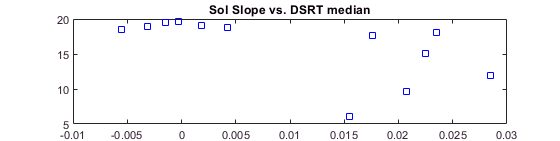

Sol = TSRT_Sol(TSRT_Sol.Group == "CP" & TSRT_Sol.Subject ~= "5117",:);
MG = TSRT_MG(TSRT_MG.Group == "CP" & TSRT_MG.Subject ~= "5117" & TSRT_MG.Subject ~= "5119",:);
Sol_DSRT = groupsummary(Sol, "Subject", 'median', "DSRT_Sol_Lat");
MG_DSRT = groupsummary(MG, "Subject", 'median', "DSRT_MG_Lat");
plot(Slope_LC_sol, table2array(Sol_DSRT(:,3)),'bs'), title('Sol Slope vs. DSRT median')

[rho, pval] = corr(table2array(Sol_DSRT(:,3)),Slope_LC_sol, 'type', 'Spearman')

rho = -0.6713

pval = 0.0204

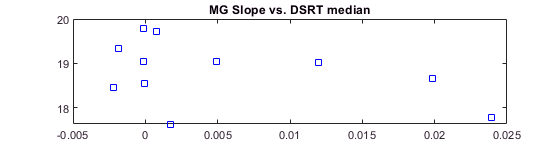

plot(Slope_LC_mg, table2array(MG_DSRT(:,3)),'bs'), title('MG Slope vs. DSRT median')

[rho, pval] = corr(table2array(MG_DSRT(:,3)),Slope_LC_mg, 'type', 'Spearman')

rho = -0.3000

pval = 0.3711

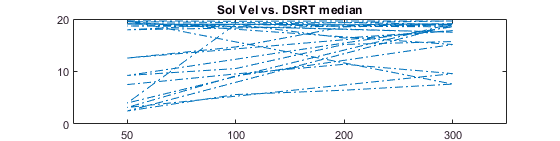

Sol_DSRT_vel = groupsummary(Sol,["Subject","Velocity_round"] , 'median', "DSRT_Sol_Lat");
MG_DSRT_vel = groupsummary(MG,["Subject","Velocity_round"] , 'median', "DSRT_MG_Lat"); 
plot(Sol_DSRT_vel.Velocity_round, Sol_DSRT_vel.median_DSRT_Sol_Lat,'-.'), title('Sol Vel vs. DSRT median')

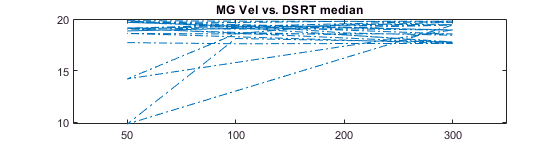

plot(MG_DSRT_vel.Velocity_round, MG_DSRT_vel.median_DSRT_MG_Lat,'-.'), title('MG Vel vs. DSRT median')